# Transducer Design

Transducer 1

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;    % 40kHz (operating frequency of transducer)
transducer_info.Pressure = 1;       % How to set this parameter?
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;      
transducer_info.rotate = [0, 0, 0];
transducer_info.medium = 'air';


% Positions and phases for the transducers (1 row)
positions = [];
for k = 1:16
    positions(k) = 0.005 + 0.01 * (k-1);
end

% PFC_PhaseCalculate_for16(target[x,y], array, focal point z(m))
phases = PFC_PhaseCalculate_for16([0.08, 0.08], [16,16], 0.2)

phases =          0    2.3562    3.9270         0    0.7854    2.3562    3.1416    3.1416    3.1416    3.1416    2.3562    0.7854         0    3.9270    2.3562         0
    2.3562    4.7124         0    2.3562    3.1416    4.7124    5.4978    5.4978    5.4978    5.4978    4.7124    3.1416    2.3562         0    4.7124    2.3562
    3.9270         0    2.3562    3.9270    5.4978         0    0.7854    1.5708    1.5708    0.7854         0    5.4978    3.9270    2.3562         0    3.9270
         0    2.3562    3.9270         0    0.7854    2.3562    3.1416    3.1416    3.1416    3.1416    2.3562    0.7854         0    3.9270    2.3562         0
    0.7854    3.1416    5.4978    0.7854    2.3562    3.9270    3.9270    4.7124    4.7124    3.9270    3.9270    2.3562    0.7854    5.4978    3.1416    0.7854
    2.3562    4.7124         0    2.3562    3.9270    4.7124    5.4978    5.4978    5.4978    5.4978    4.7124    3.9270    2.3562         0    4.7124    2.3562
    3.1416    5.4978    0

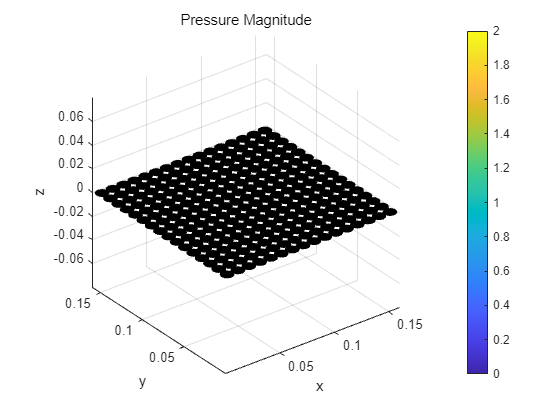

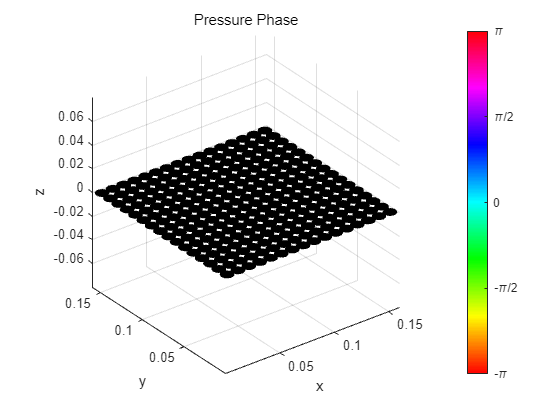

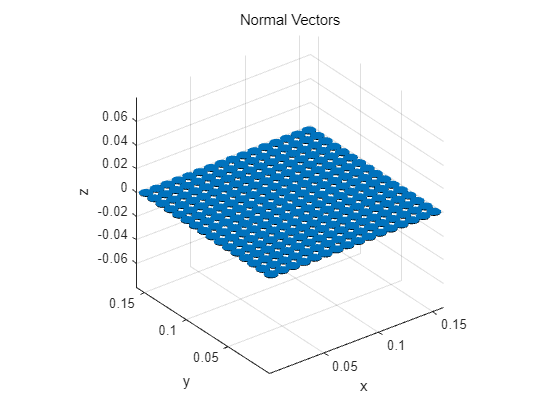

% phases = PFC_PhaseCalculate([0.08, 0.08], [16,16], 0.2)

% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:16
    for j = 1:16
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];

        % transducer_info.Phase = phases(i,j);
        transducer_info.Phase = phases(i,j);
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);

        % Increment index for next transducer
        index = index + 1;
    end
end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = 0 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_y = 0 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_z = 150e-3 : 0.5e-3 : 250e-3;          % Simulation Area

## Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.08, reading_pos_z);

Started at 2024-06-17 14:16:16
Finished at 2024-06-17 14:28:36
Progressed time : 00:12:20


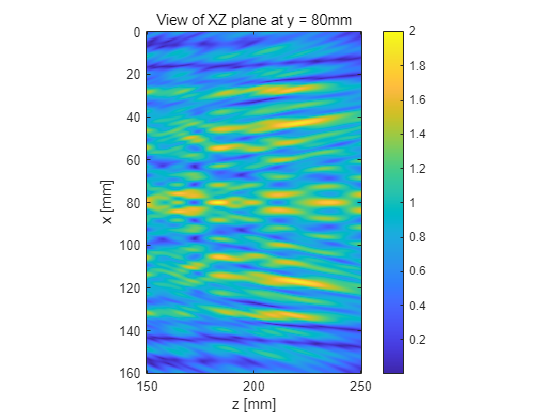


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 80mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');



% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.2);

Started at 2024-06-17 14:28:37
Finished at 2024-06-17 14:48:02
Progressed time : 00:19:24


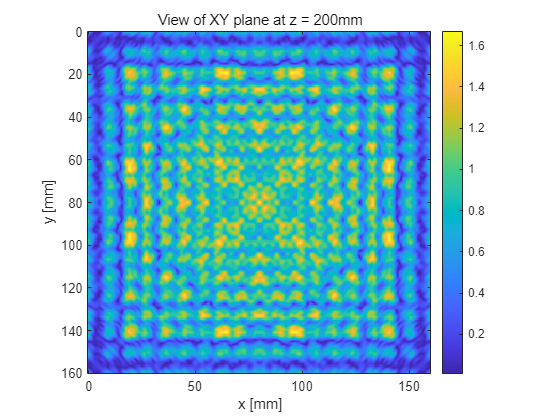


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 200mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');